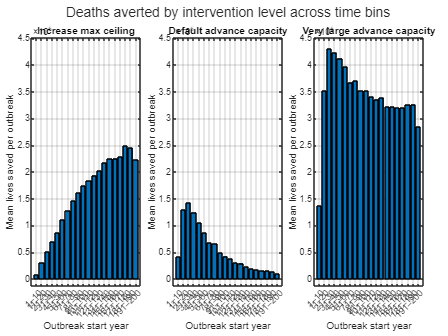

keyVars = {'sim_num', 'yr_start', 'pathogen'};

% Paths
progDir = fullfile('C:\Users\squaade\Documents\Github\pandemic_model\output\jobs\allrisk_base_program_levels_small\raw\chunk_1');
sensDir = fullfile('C:\Users\squaade\Documents\Github\pandemic_model\output\sensitivity\baseline_vaccine_program_small');

% Load pandemic tables
prog_base  = load(fullfile(progDir, 'baseline_pandemic_table.mat')).pandemic_table;
prog_adv100 = load(fullfile(progDir, 'advance_capacity_share_100_pandemic_table.mat')).pandemic_table;
prog_adv200 = load(fullfile(progDir, 'advance_capacity_share_200_pandemic_table.mat')).pandemic_table;
sens_base = load(fullfile(sensDir, 'baseline', 'raw', 'chunk_1', 'baseline_pandemic_table.mat')).pandemic_table;
sens_max2 = load(fullfile(sensDir, 'max_capacity', 'value_2', 'raw', 'chunk_1', 'baseline_pandemic_table.mat')).pandemic_table;

%% 1) Increase max ceiling (baseline sensitivity vs max_capacity value_2)
A = sens_base(:, [keyVars, {'m_deaths'}]);
B = sens_max2(:, [keyVars, {'m_deaths'}]);
A.Properties.VariableNames{'m_deaths'} = 'm_deaths_ref';
B.Properties.VariableNames{'m_deaths'} = 'm_deaths_hi';
J1 = innerjoin(A, B, 'Keys', keyVars);
J1.delta_m_deaths = J1.m_deaths_ref - J1.m_deaths_hi; % positive = deaths averted
J1.bin10 = ceil(J1.yr_start / 10);
G1 = groupsummary(J1, 'bin10', 'mean', 'delta_m_deaths');
L1 = arrayfun(@(b) sprintf('%d–%d', 10*(b-1)+1, 10*b), G1.bin10, 'UniformOutput', false);

%% 2) Default advance capacity (program baseline vs advance_capacity_share_100)
A = prog_base(:, [keyVars, {'m_deaths'}]);
B = prog_adv100(:, [keyVars, {'m_deaths'}]);
A.Properties.VariableNames{'m_deaths'} = 'm_deaths_ref';
B.Properties.VariableNames{'m_deaths'} = 'm_deaths_hi';
J2 = innerjoin(A, B, 'Keys', keyVars);
J2.delta_m_deaths = J2.m_deaths_ref - J2.m_deaths_hi; % positive = deaths averted
J2.bin10 = ceil(J2.yr_start / 10);
G2 = groupsummary(J2, 'bin10', 'mean', 'delta_m_deaths');
L2 = arrayfun(@(b) sprintf('%d–%d', 10*(b-1)+1, 10*b), G2.bin10, 'UniformOutput', false);

%% 3) Very large advance capacity (program baseline vs advance_capacity_share_200)
A = prog_base(:, [keyVars, {'m_deaths'}]);
B = prog_adv200(:, [keyVars, {'m_deaths'}]);
A.Properties.VariableNames{'m_deaths'} = 'm_deaths_ref';
B.Properties.VariableNames{'m_deaths'} = 'm_deaths_hi';
J3 = innerjoin(A, B, 'Keys', keyVars);
J3.delta_m_deaths = J3.m_deaths_ref - J3.m_deaths_hi; % positive = deaths averted
J3.bin10 = ceil(J3.yr_start / 10);
G3 = groupsummary(J3, 'bin10', 'mean', 'delta_m_deaths');
L3 = arrayfun(@(b) sprintf('%d–%d', 10*(b-1)+1, 10*b), G3.bin10, 'UniformOutput', false);

%% Plot panel
figure('Color', 'w');
t = tiledlayout(1, 3, 'Padding', 'compact', 'TileSpacing', 'compact');
ax1 = nexttile(t);
bar(ax1, categorical(L1, L1, 'Ordinal', true), G1.mean_delta_m_deaths);
grid(ax1, 'on'); xtickangle(ax1, 45);
title(ax1, 'Increase max ceiling');
xlabel(ax1, 'Outbreak start year');
ylabel(ax1, 'Mean lives saved per outbreak');
ax2 = nexttile(t);
bar(ax2, categorical(L2, L2, 'Ordinal', true), G2.mean_delta_m_deaths);
grid(ax2, 'on'); xtickangle(ax2, 45);
title(ax2, 'Default advance capacity');
xlabel(ax2, 'Outbreak start year');
ylabel(ax2, 'Mean lives saved per outbreak');
ax3 = nexttile(t);
bar(ax3, categorical(L3, L3, 'Ordinal', true), G3.mean_delta_m_deaths);
grid(ax3, 'on'); xtickangle(ax3, 45);
title(ax3, 'Very large advance capacity');
xlabel(ax3, 'Outbreak start year');
ylabel(ax3, 'Mean lives saved per outbreak');

% Force same y scale across all panels
yall = [G1.mean_delta_m_deaths; G2.mean_delta_m_deaths; G3.mean_delta_m_deaths];
ypad = 0.05 * (max(yall) - min(yall) + eps);
yl = [min(yall) - ypad, max(yall) + ypad];
ylim(ax1, yl); ylim(ax2, yl); ylim(ax3, yl);
linkaxes([ax1 ax2 ax3], 'y');
title(t, 'Deaths averted by intervention level across time bins');
exportgraphics(gcf, fullfile('output', 'adv_cap_comparison.jpg'), 'Resolution', 600);